[cbAudio, cbFs] = audioread('common_blackbird_long.wav');
% convert to mono
cbAudio = mono(cbAudio);
% trim the first bit of silence
cbAudio = cbAudio(1.5*cbFs:end);
% normalize
cbAudio = normalize(cbAudio)/8;

cb = cbAudio;
fs = cbFs;

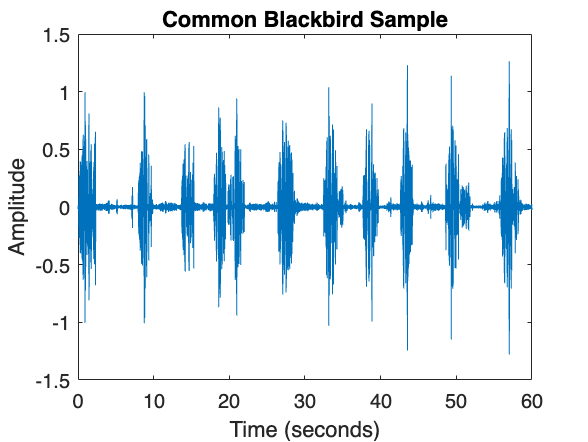

plot((0:numel(cbAudio)-1)/cbFs,cbAudio)
title('Common Blackbird Sample')
xlabel('Time (seconds)')
ylabel('Amplitude')

envelope = abs(hilbert(cb));

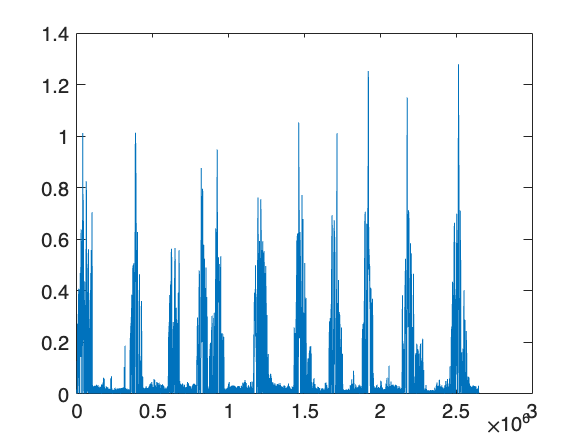

plot(envelope)

threshold = 0.2;
segmentIndices = find(envelope > threshold);
segmentTimes = segmentIndices / fs;

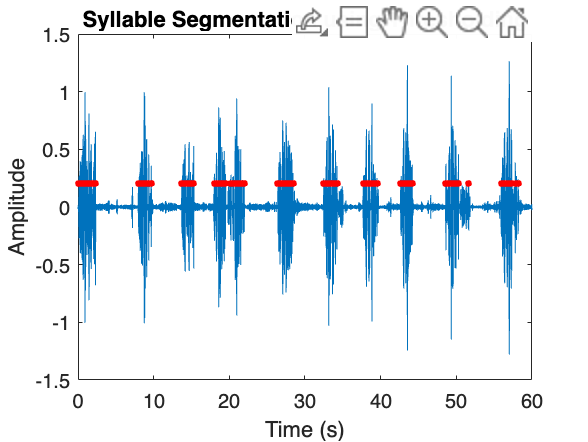

t = (0:length(cb)-1) / fs;
figure;
plot(t, cb);
hold on;
plot(segmentTimes, threshold*ones(size(segmentTimes)), 'r.', 'MarkerSize', 10);
hold off;
xlabel('Time (s)');
ylabel('Amplitude');
title('Syllable Segmentation using Thresholding');

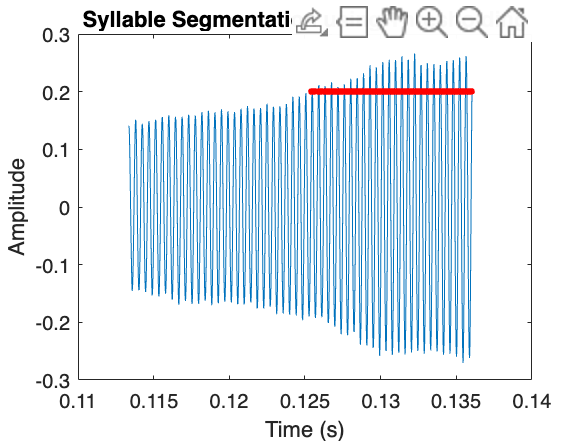

zoomIn = 6000;
segmentTimesZoomed = segmentTimes((segmentTimes * fs) < zoomIn & (segmentTimes * fs) > 5000);
figure;
plot(t(5000:zoomIn), cb(5000:zoomIn));
hold on;
plot(segmentTimesZoomed, threshold*ones(size(segmentTimesZoomed)), 'r.', 'MarkerSize', 10);
hold off;
xlabel('Time (s)');
ylabel('Amplitude');
title('Syllable Segmentation using Thresholding');